stock_data_dir = dir('C:\Users\wynga\OneDrive\Desktop\PhD_Research\Options Trading\Stock Data');
stock_data_dir = stock_data_dir(~[stock_data_dir(:).isdir]);

num_stocks = length(stock_data_dir);
stock_data_names{num_stocks} = 'Placeholder';
stock_data_array{num_stocks} = struct();

clear("black_scholes_params_array")
for index = 1:num_stocks
    filename = stock_data_dir(index).name;
    stock_data_names{index} = filename(1:end-4);
    filepath = horzcat(stock_data_dir(index).folder,'\',filename);
    stock_data = read_yahoo_finance_csv(filepath);
    stock_data_array{index} = stock_data;
    black_scholes_params_array(index) = estimate_black_scholes_parameters(stock_data,'Open',1); % Assuming We Use Opening Price
end


%% Get Drift Rates and Volatities; Compare to Historical Volatility

% min_volatilities = [black_scholes_params_array(:).sigma_min]
% historical_volatilities  = [30.69 18.65 17.83 12.55 12.49 21.89 17.78 13.48 33.01 22.72] / 100
% max_volatilities = [black_scholes_params_array(:).sigma_max]
% 
% 
% historical_volatilities  = [30.69 18.65 17.83 12.55 12.49 21.89 17.78 13.48 33.01 22.72] / 100
% estimated_volatilities = [black_scholes_params_array(:).best_sigma]


% Correlations 

correlation_matrix = nan(num_stocks,num_stocks);
for row_index = 1:num_stocks
    for column_index = 1:num_stocks
        correlation_matrix(row_index,column_index) = corr([stock_data_array{row_index}.Open]',[stock_data_array{column_index}.Open]');
        % Correlation function verified
    end
end

stock_data_names;
correlation_matrix;
% Correlation function verified


% Options Chains ( 1 Stock Example)

spot_price = 63.80;
KO_option_types = {'Call' 'Call' 'Call' 'Call' 'Call' 'Call' 'Call' 'Call' 'Call' 'Call'};
KO_option_strikes = [60 61 62 63 64 65 66 67 68 69];
KO_option_prices = [4.35 4.95 2.4 1.37 .67 .27 .22 .05 .72 .5];
time_to_expiration = 17/365;
max_price = 100;

KO_expected_values = nan(1,10);
KO_standard_deviations = nan(1,10);

mu = black_scholes_params.best_mu

mu = 0.0732

sigma = black_scholes_params.best_sigma

sigma = 0.1327

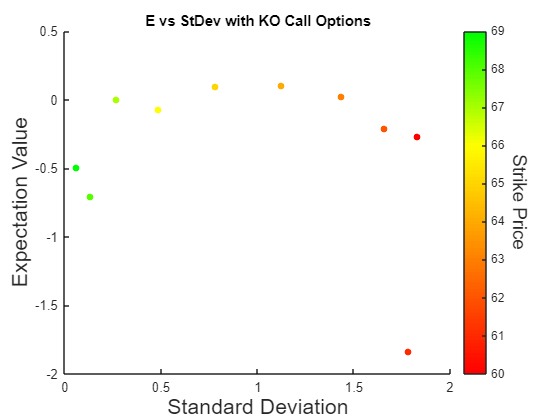


for index = 1:length(KO_option_types)
    black_scholes_params = black_scholes_params_array(strcmpi(stock_data_names,'KO'));
    mu = black_scholes_params.best_mu;
    sigma = black_scholes_params.best_sigma;
    option_type = KO_option_types{index};
    option_price = KO_option_prices(index);
    strike_price = KO_option_strikes(index);
    [expected_value,variance] = black_scholes_expected_value(spot_price,mu,sigma,time_to_expiration,...
                            option_type,option_price,strike_price,'max_price',max_price);
    standard_deviation = sqrt(variance);
    KO_expected_values(index) = expected_value;
    KO_standard_deviations(index) = standard_deviation;
end


figure
hold on
for index = 1:length(KO_option_types)
    strike_percentile = (KO_option_strikes(index)-min(KO_option_strikes)) / (max(KO_option_strikes)-min(KO_option_strikes));
    red_value = min(3-3*strike_percentile,1);
    green_value = min(3/2*strike_percentile,1);
    blue_value = 0;
    plot_color = [red_value,green_value,blue_value];    
    plot(KO_standard_deviations(index),KO_expected_values(index),'LineStyle','none','Marker','.','Color',plot_color,'MarkerSize',15)
end
xlabel('Standard Deviation','FontSize',16)
ylabel('Expectation Value','FontSize',16)
title('E vs StDev with KO Call Options')

% Colorbar
the_colorbar = colorbar('Ticks',KO_option_strikes);
clim([min(KO_option_strikes) max(KO_option_strikes)])
strike_percentiles = 0:.01:1;
red_values = min(3-3*strike_percentiles,1)';
green_values = min(3/2*strike_percentiles,1)';
blue_values = zeros(1,length(strike_percentiles))';
colormap([red_values, green_values, blue_values])
ylabel(the_colorbar,'Strike Price','Rotation',270,'FontSize',14)